# **JacobiAM**

[Jacobi Amplitude Function](https://dlmf.nist.gov/22.16#i)

## Definition


$$\mathrm{am}\left(x\left|m\right.\right)\equiv \int_0^x \mathrm{dn}\left(t\left|m\right.\right)\;\textrm{dt}$$



$$\mathrm{am}\left(x,k\right)\equiv \mathrm{am}\left(x\left|k^2 \right.\right)$$


where *k *is the modulus and *m *is the parameter, $\textrm{dn}\left(t\left|m\right.\right)$ is  the Jacobi elliptic function *dn*. 

Domain: If $-\infty <m<1$ then $-\infty \le x\le \infty$ (quasi-periodic function). If $m>1$then $-\infty \le x\le \infty$ (periodic function).  For the specified domain, the  codomain is the set of real numbers.

Basic features:

$\mathrm{am}\left(-x\left|m\right.\right)=-\mathrm{am}\left(x\left|m\right.\right)$   (odd) 

 $\mathrm{am}\left(x+2\textrm{K}\left(m\right)\left|m\right.\right)=\mathrm{am}\left(x|m\right)+\pi ,\;\;\;\left|x\right|\le K\left(m\right)$  (quasi-periodic)

Special values:

$\mathrm{am}\left(0\left|m\right.\right)=0$,   $\textrm{am}\left(K\left(m\right)\left|m\right.\right)=\frac{\pi }{2}$

$\mathrm{am}\left(x\left|0\right.\right)=x$,  $\mathrm{am}\left(x\left|1\right.\right)=\mathrm{gd}\;x$

Identities:

$\textrm{am}\left(x\left|m\right.\right)=\tan^{-1} \left(\frac{\textrm{sd}\left(x\sqrt{m}\left|m^{-1} \right.\right)}{\sqrt{m}}\right)$,   $\;m>1$


$$F\left(\mathrm{am}\left(x|m\right)|m\right)=x$$


$\mathrm{sn}\;x=\mathrm{sin}\;\mathrm{am}\left(x|m\right)$,    $\mathrm{cn}\;x=\mathrm{cos}\;\textrm{am}\left(x\left|m\right.\right)$


$$E\left(\mathrm{am}\left(x|m\right)|m\right)=\epsilon \left(x\left|m\right.\right)$$


$F\left(\phi \left|m\right.\right)\;$and $E\left(\phi \left|m\right.\right)\;$are Legendre form of elliptic integrals of the first and the second kind, $K\left(m\right)$ and $E\left(m\right)$ are complete elliptic integrals of the first and the second kind, $\;\epsilon \left(x\left|m\right.\right)$ is the Jacobi epsilon function, $\mathrm{sd}\left(x|m\right)$is tha Jacobi elliptic function *sd*, $\textrm{gd}\;x$ is the Gudermannian function .

## Syntax

Y = JacobiAM(X,K)

y = jam(x,k)

Y = mJacobiAM(X,M)

y = mjam(x,m)

## Description

**Y = JacobiAM(X,K)** returns the Jacobi amplitude function $\mathrm{am}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **JacobiAM** is the wrapper function which calls the functions **jam** element-wise via the function **ufun2**.

**y = jam(x,k)** returns the Jacobi amplitude function $\mathrm{am}\left(x,k\right)$ for argument x and the modulus k. It is assumed that  the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed. **jam** is the wrapper function which calls the functions **mjam**.

**Y = mJacobiAM(X,M) **returns the Jacobi amplitude function $\mathrm{am}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mJacobiAM** is the wrapper function which calls the function **mjam** element-wise via the function **ufun2**.

**y = mjam(x,m) **returns the Jacobi amplitude function $\mathrm{am}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that  arguments are real scalars without check. y is NaN if any of  the arguments is invalid or convergence failed.   **mjam** calculte  $\mathrm{am}\left(x\left|m\right.\right)$ using the function **sncndn  **([1])

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5; 
x = 0.5;
[jam(x,k), JacobiAM(x,k), mjam(x,k^2), mJacobiAM(x,k^2)]

ans =    0.495058281122736   0.495058281122736   0.495058281122736   0.495058281122736


Accuracy

fprintf('%.16g\n',jam(0.5,2))

0.4238993408385583


% Maple 0.4238993408385584_22

fprintf('%.16g\n',jam(0.5,0.5))

0.4950582811227363


% Maple  o.4950582811227364_50

fprintf('%.16g\n',mjam(0.5,-4))

0.5823897319938066


% Maple 0.5823897319938066_33


[MATLAB example](https://www.mathworks.com/help/symbolic/jacobiam.html)

fprintf('%.16g\n',mjam(3,5))

0.03114981541243091


% MATLAB 3.1104428381773623934754349126446  %% This is wrong
% Maple  0.03114981541243085_03

Special values

m = -20;
x = -0.5; 
mjam(0,m)

ans = 0

disp(mjam(melK(m),m)-pi/2)  

     4.440892098500626e-16



disp(mjam(x,0) - x)  

     0



disp(mjam(x,1) - gd(x))  % gd is Gudermannian function

     0



mjam(0,m)

ans = 0

Identities

m = -2; 
x = 0.5; % |x| <= 1
mJacobiAM(-x,m) + mJacobiAM(x,m) % odd function

ans = 0

disp(sin(mJacobiAM(x,m)) - mJacobiSN(x,m))  % definition

     0



m = 2; %
disp(cos(mJacobiAM(x,m)) - mJacobiCN(x,m))  % definition

     0



k = 0.5;
disp(pelF(jam(x,k),k)-x)  

    -1.665334536937735e-16



m = 2; % |m|>1
disp(mjam(x,m)-atan(mjsd(sqrt(m)*x,1/m)/sqrt(m)))

     5.551115123125783e-17



**Vector input**

X = [ 1, 2, 4];
K = [-2, 3, 4]; % |K|>1
disp(JacobiAM(X,K)-atan(JacobiSD(K.*X,1./K)./K))

     0     0     0



**Matrix input**

X = [ 1, 2, 4; -2, -3, -4];
M = [2, 3, 4; 10, 20, 30];
disp(mJacobiAM(X,M)-atan(mJacobiSD(sqrt(M).*X,1./M)./sqrt(M)))

   1.0e-15 *

   0.111022302462516                   0                   0
  -0.006938893903907                   0  -0.006938893903907



## **Graphs **

**Example 1**

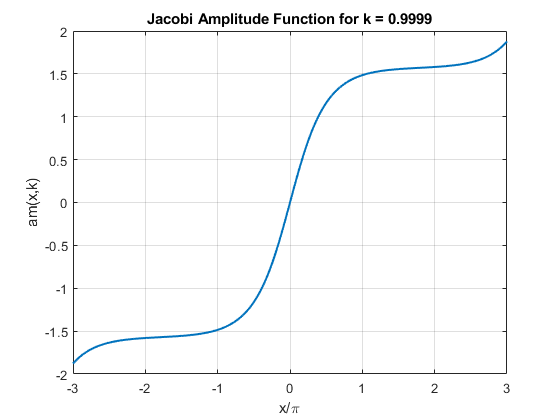

figure
x=-3:0.01:3;
k = 0.9999;
plot(x,JacobiAM(pi*x,k),'LineWidth',1.5)
xlabel('x/\pi')
ylabel('am(x,k)')
title(sprintf('Jacobi Amplitude Function for k = %g',k))
grid on

**Example 2**

Example from NIST Mathematical Functions Handbook (Fig 22.16.1)

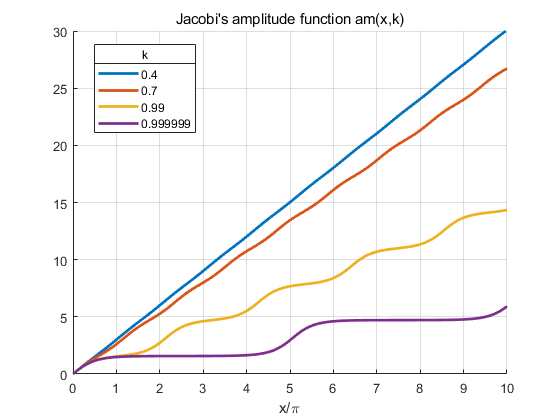

figure
clf
hold on
npts = 100;
k = [0.4, 0.7, 0.99, 0.999999];
s = pi;
xlim =  10;
x = linspace( 0, xlim, npts);
xx = x*s;
nn = length(k);
txt{nn}=[];
for n = 1:nn
    txt{n} = num2str(k(n),6);
    plot(x,JacobiAM(xx,k(n)),'LineWidth',2)
end
hlg = legend(txt,'Location','best');
title(hlg, 'k','FontWeight','normal')
xlabel('x/\pi')
ylim([0, 30]);
title('Jacobi''s amplitude function am(x,k)','FontWeight','normal')
grid on
hold off

Example from NIST Mathematical Functions Handbook (Fig 22.19.1)

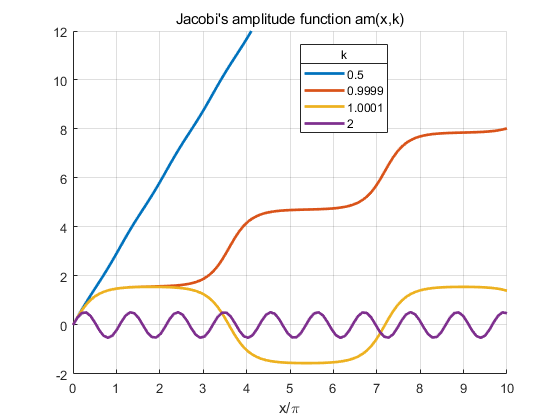

figure
clf
hold on
npts = 100;
k = [0.5, 0.9999, 1.0001, 2];
s = pi;
xlim =  10;
x = linspace( 0, xlim, npts);
xx = x*s;
nn = length(k);
txt{nn}=[];
for n = 1:nn
    txt{n} = num2str(k(n),6);
    plot(x,JacobiAM(xx,k(n)),'LineWidth',2)
end
hlg = legend(txt,'Location','best');
title(hlg, 'k','FontWeight','normal')
xlabel('x/\pi')
ylim([-2, 12]);
title('Jacobi''s amplitude function am(x,k)','FontWeight','normal')
grid on
hold off

**Example 3**

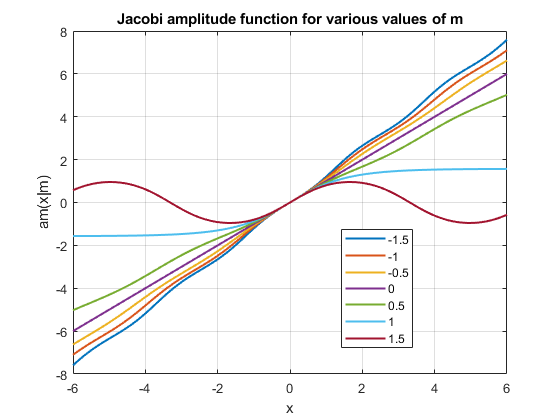

figure
X = -6:0.1:6;
M = -1.5:0.5:1.5;
EPS = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    EPS(i,:) = mJacobiAM(X,M(i));
end
plot(X,EPS,'LineWidth',1.5)
%axis([min(X) max(X) -1.2 1.2])
grid on
legend(clg,'Location','Best')
title('Jacobi amplitude function for various values of m')
xlabel('x')
ylabel('am(x|m)')

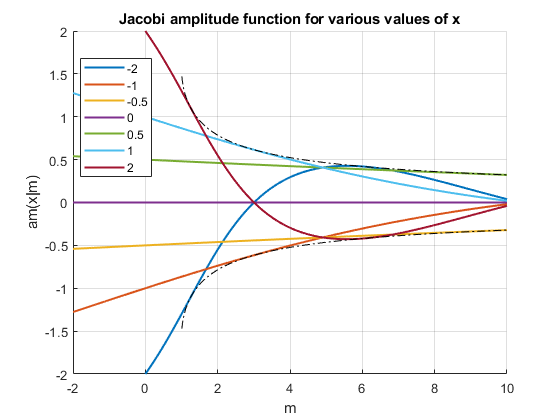

figure
hold on
M = -2:0.01:10;
X = [-2,-1,-0.5,0,0.5,1,2];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mJacobiAM(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -3 3])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Jacobi amplitude function for various values of x')
xlabel('m')
ylabel('am(x|m)')
M = 0:0.01:10;
F = mJacobiAM(mEllipticK(1./M)./sqrt(abs(M)),M);
plot(M,F,'k-.')
plot(M,-F,'k-.')
ylim([-2 2])
hold off

**Example 4**

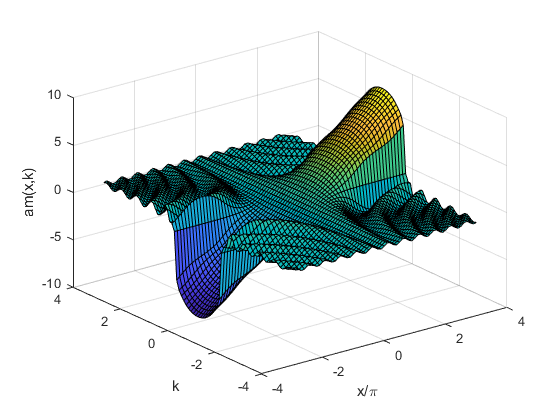

figure
x=-3:0.1:3;
k=-4:0.1:4;
[X,K]=meshgrid(x,k);
surface(X,K,JacobiAM(pi*X,K))
view(3)
xlabel('x/\pi')
ylabel('k')
zlabel('am(x,k)')
grid on

**Example 5**

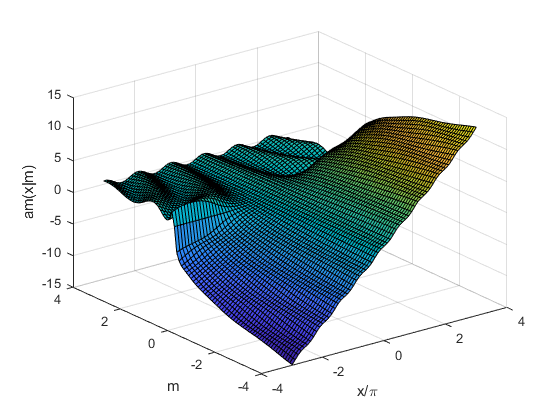

figure
x=-3:0.1:3;
m=-4:0.1:4;
[X,M]=meshgrid(x,m);
surface(X,M,mJacobiAM(pi*X,M))
view(3)
xlabel('x/\pi')
ylabel('m')
zlabel('am(x|m)')
grid on

**Example 6**

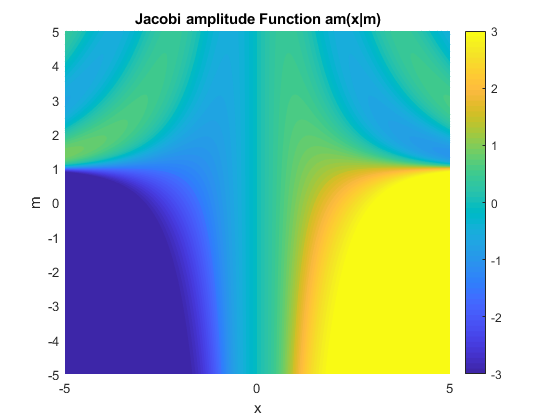

figure
f = @(x,m)mJacobiAM(x,m);
fcontour(f,'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title('Jacobi amplitude Function am(x|m)')
xlabel('x')
ylabel('m')
colorbar
grid on

**Example 7**

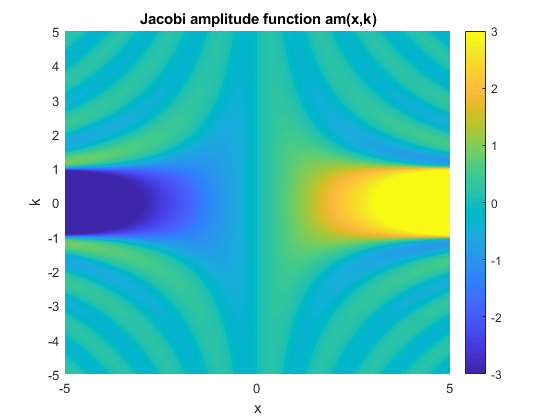

figure
f = @(x,k)JacobiAM(x,k);
fcontour(f,'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title('Jacobi amplitude function am(x,k)')
xlabel('x')
ylabel('k')
colorbar
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] R. Bulirsch, Numerical Calculation of Elliptic Integrals and Elliptic Functions. Numerische Mathematik 7, 78-90, 1965

## See Also